% 1. 
file = '/Users/liujiyao/Documents/2022课程/医学图像处理/作业/3Exercise/ASL_PWI.nii'
ASL_PWI = spm_vol(file);
ASL = imrotate(spm_read_vols(ASL_PWI),90);
img = ASL(:,:,18);
imshow(img);

% 2.
img18 = uint8((img - min(img(:))) * 255 / (max(img(:)) - min(img(:))));
imshow(img18);

%  3. 
img18(img18<=40)=0;  % 去掉背景 阈值为40；
mask = img18;
mask(mask>0)=255;  % 转为二值图
se = strel('disk',5);
mask = imopen(mask, se);
% mask = imerode(mask,se);
% mask = imdilate(mask,se);
mask = imclose(mask, se);
imshow(mask);

% 4.
tof_vol = spm_vol(['/Users/liujiyao/Documents/2022课程/医学图像处理/作业/2 Exercise/TOF_nii/Mag.nii' ...
    '']);
mat = tof_vol.mat

mat =    -0.3787    0.0055    0.0099   95.5035
    0.0042    0.3740   -0.0794 -101.5306
    0.0083    0.0601    0.4935  -58.2914
         0         0         0    1.0000



res = [norm(mat(:,1)), norm(mat(:,2)), norm(mat(:,3)), norm(mat(:,4))]

res =     0.3788    0.3788    0.5000  151.0903



dicom = dicominfo('/Users/liujiyao/Documents/2022课程/医学图像处理/作业/2 Exercise/TOF_Dicom/Mag (0001).dcm');
dicom.PixelSpacing

ans =     0.3788
    0.3788


dicom.SpacingBetweenSlices

ans = 0.5000

% 5 a
ref_vol = spm_vol('/Users/liujiyao/Documents/2022课程/医学图像处理/作业/3Exercise/ASL_PWI.nii');
to_reslice_vol = spm_vol('/Users/liujiyao/Documents/2022课程/医学图像处理/作业/3Exercise/T1W.nii');
prefix = 'resliced_';
resflags = struct(...
    'mask',0,... % will not mask anything
    'mean',0,... % will not write mean image
    'which',1,... % write only the coregistered file
    'interp',1,... 
    'prefix', prefix);
spm_reslice([ref_vol; to_reslice_vol], resflags); 

SPM12: spm_reslice (v7141)                         23:46:20 - 22/09/2022
Completed                               :          23:46:21 - 22/09/2022



result_nii = spm_vol('/Users/liujiyao/Documents/2022课程/医学图像处理/作业/3Exercise/resliced_T1W.nii')

result_nii = 包含以下字段的 struct :
      fname: '/Users/liujiyao/Documents/2022课程/医学图像处理/作业/3Exercise/resliced_T1W.nii'
        dim: [128 128 30]
         dt: [4 0]
      pinfo: [3×1 double]
        mat: [4×4 double]
          n: [1 1]
    descrip: 'spm - realigned'
    private: [1×1 nifti]


result = imrotate(spm_read_vols(result_nii),90);
imshow(result(:,:,18)) 


imshow(ASL(:,:,18))

% 5 b 
ref_vol = spm_vol('/Users/liujiyao/Documents/2022课程/医学图像处理/作业/3Exercise/ASL_PWI.nii');
to_reslice_vol = spm_vol('/Users/liujiyao/Documents/2022课程/医学图像处理/作业/3Exercise/T1W.nii');
prefix = 'resliced2_';
resflags2 = struct(...
    'mask',0,... % will not mask anything
    'mean',0,... % will not write mean image
    'which',1,... % write only the coregistered file
    'interp',1,... 
    'prefix', prefix);
spm_reslice([to_reslice_vol; ref_vol], resflags2); 

SPM12: spm_reslice (v7141)                         00:01:11 - 23/09/2022
Completed                               :          00:01:12 - 23/09/2022


result_nii = spm_vol('/Users/liujiyao/Documents/2022课程/医学图像处理/作业/3Exercise/resliced2_ASL_PWI.nii')

result_nii = 包含以下字段的 struct :
      fname: '/Users/liujiyao/Documents/2022课程/医学图像处理/作业/3Exercise/resliced2_ASL_PWI.nii'
        dim: [256 256 146]
         dt: [4 0]
      pinfo: [3×1 double]
        mat: [4×4 double]
          n: [1 1]
    descrip: 'spm - realigned'
    private: [1×1 nifti]


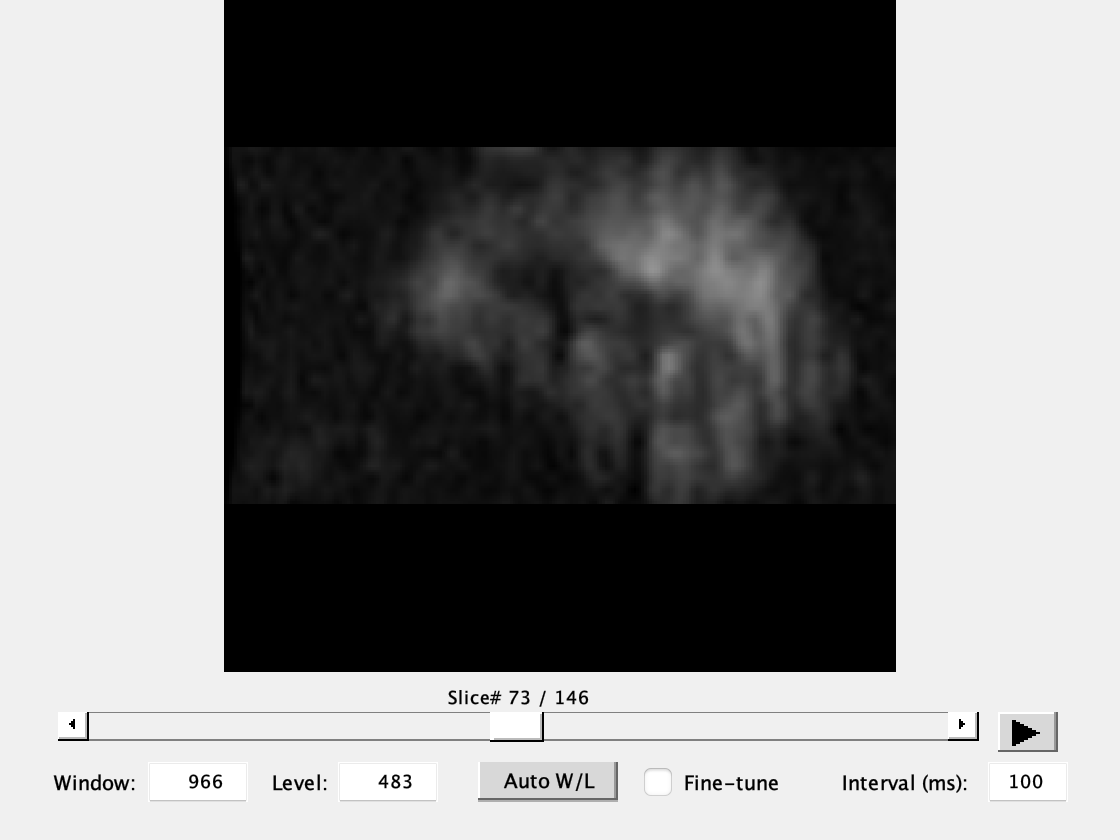

result = imrotate(spm_read_vols(result_nii),90);
figure, imshow3D(result)

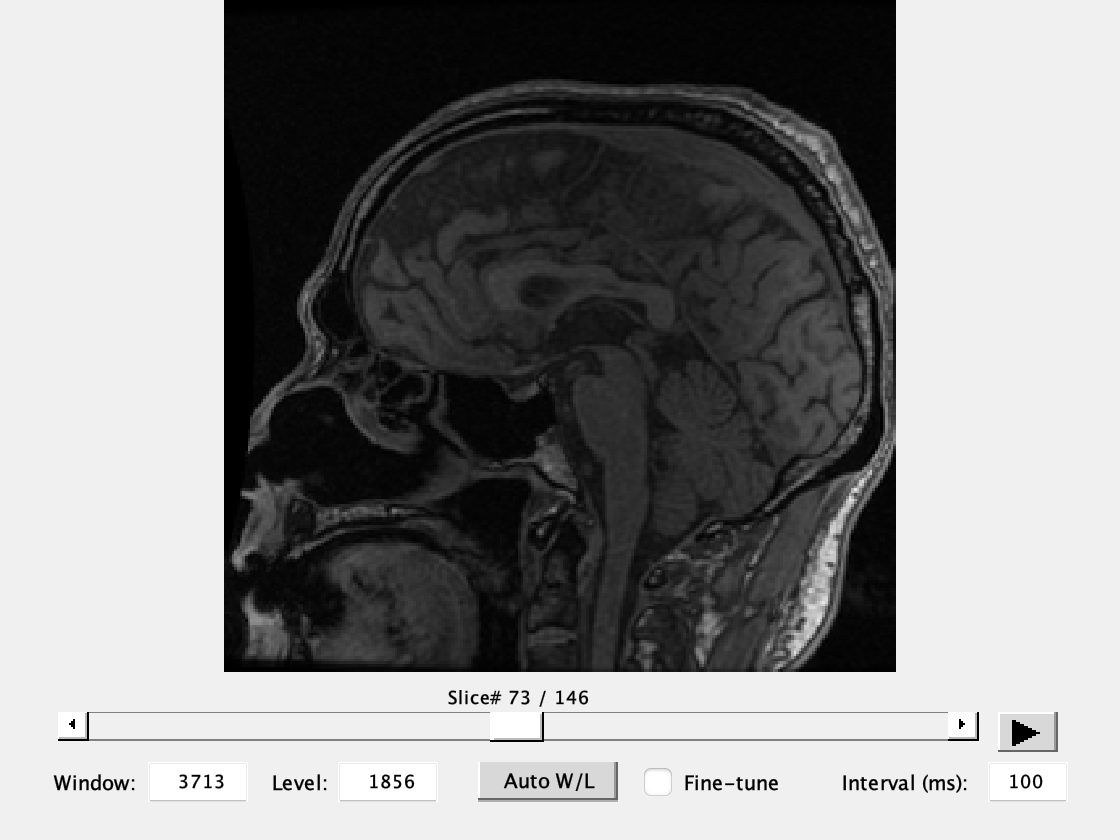

imgT1W = imrotate(spm_read_vols(to_reslice_vol),90);
figure, imshow3D(imgT1W)